clear

Cp_paper = flip([0.005, 0.04, 0.19, 0.13, 0.1, 0])

Cp_paper =          0    0.1000    0.1300    0.1900    0.0400    0.0050


TSR = flip([1.2, 1, 0.8, 0.6, 0.4, 0])

TSR =          0    0.4000    0.6000    0.8000    1.0000    1.2000


Cp=@(xq) (xq<1.2 & xq>0).*pchip(TSR,Cp_paper,xq)

Cp = function_handle with value:
    @(xq)(xq<1.2&xq>0).*pchip(TSR,Cp_paper,xq)


xq=linspace(0,1.2,100)

xq =          0    0.0121    0.0242    0.0364    0.0485    0.0606    0.0727    0.0848    0.0970    0.1091    0.1212    0.1333    0.1455    0.1576    0.1697    0.1818    0.1939    0.2061    0.2182    0.2303    0.2424    0.2545    0.2667    0.2788    0.2909    0.3030    0.3152    0.3273    0.3394    0.3515    0.3636    0.3758    0.3879    0.4000    0.4121    0.4242    0.4364    0.4485    0.4606    0.4727    0.4848    0.4970    0.5091    0.5212    0.5333    0.5455    0.5576    0.5697    0.5818    0.5939


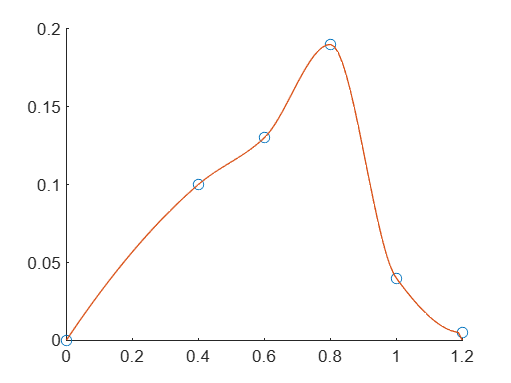

scatter(TSR,Cp_paper)
hold on
plot(xq,Cp(xq))
hold off


function dydt=odefun(t,y,V_air,TSR_f,Cp,K_f,R_eje,m_tur,R_tur,J,A)
    rho=1.1;
    %TSR_t=TSR_f(y,V_air(t),R_tur);
    Cp_t=Cp(y);
    %T_f=K_f*m_tur*9.81*R_eje*sign(y);
    c=1e-5;
    T_f=y*c;
    T_tur=0.5*rho*A*(V_air(t)^2)*R_tur*Cp_t/y;
    dydt=(T_tur-T_f)/J;
    %Modelo dinamico adimensional usa TSR y tiempo adimensional
end

V_air=@(t) 3;
TSR_f=@(omega,V_air,R_tur) omega*R_tur/V_air;

c=1e-5

c = 1.0000e-05

rho=1.1;
J=2e-5

J = 2.0000e-05

A_f=51e-3*51e-3

A_f = 0.0026

R_tur=25.5e-3

R_tur = 0.0255

R_eje=2.5e-3

R_eje = 0.0025

m_tur=7e-3

m_tur = 0.0070

K_f=0.4

K_f = 0.4000

T_f=100

T_f = 100

Tf_adim=T_f*R_tur/V_air(0)

Tf_adim = 0.8500


%ecuacion diferencial adimensional
[t_adim,TSR_t]=ode89(@(t,y) odefun(t,y,V_air,TSR_f,Cp,K_f,R_eje,m_tur,R_tur,J,A_f),[0,Tf_adim],0.001)

t_adim =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0001
    0.0001


TSR_t =     0.0010
    0.0010
    0.0011
    0.0011
    0.0012
    0.0012
    0.0013
    0.0013
    0.0014
    0.0016



omega=TSR_t.*V_air(t_adim)/R_tur

omega =     0.1176
    0.1231
    0.1286
    0.1340
    0.1395
    0.1449
    0.1504
    0.1559
    0.1613
    0.1886


t=t_adim*V_air(t_adim)/R_tur

t =          0
    0.0011
    0.0021
    0.0032
    0.0042
    0.0053
    0.0063
    0.0074
    0.0084
    0.0137


alpha=gradient(omega,t)

alpha =     5.1950
    5.1949
    5.1948
    5.1946
    5.1945
    5.1943
    5.1942
    5.1940
    5.1936
    5.1931


T=J*alpha

T = 1.0e-03 *

    0.1039
    0.1039
    0.1039
    0.1039
    0.1039
    0.1039
    0.1039
    0.1039
    0.1039
    0.1039


%T_corregido=T+K_f*m_tur*9.81*R_eje
T_corregido=T+TSR_t*c

T_corregido = 1.0e-03 *

    0.1039
    0.1039
    0.1039
    0.1039
    0.1039
    0.1039
    0.1039
    0.1039
    0.1039
    0.1039


CT=T./(0.5*rho*A_f*R_tur*V_air(t)^2)

CT =     0.3165
    0.3165
    0.3165
    0.3164
    0.3164
    0.3164
    0.3164
    0.3164
    0.3164
    0.3164


CT_corregido=T_corregido./(0.5*rho*A_f*R_tur*V_air(t)^2)

CT_corregido =     0.3165
    0.3165
    0.3165
    0.3165
    0.3165
    0.3165
    0.3165
    0.3164
    0.3164
    0.3164


Cp_t=TSR_t.*CT

Cp_t =     0.0003
    0.0003
    0.0003
    0.0004
    0.0004
    0.0004
    0.0004
    0.0004
    0.0004
    0.0005


Cp_t_corregido=TSR_t.*CT_corregido

Cp_t_corregido =     0.0003
    0.0003
    0.0003
    0.0004
    0.0004
    0.0004
    0.0004
    0.0004
    0.0004
    0.0005


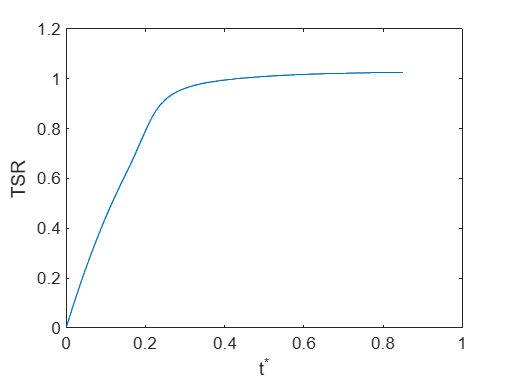


plot(t_adim,TSR_t)
xlabel("t^*")
ylabel("TSR")

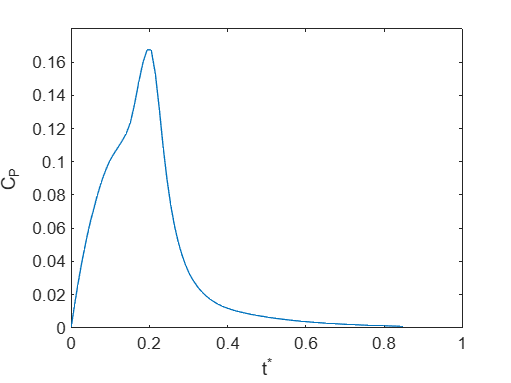

plot(t_adim,Cp_t)
xlabel("t^*")
ylabel("C_P")

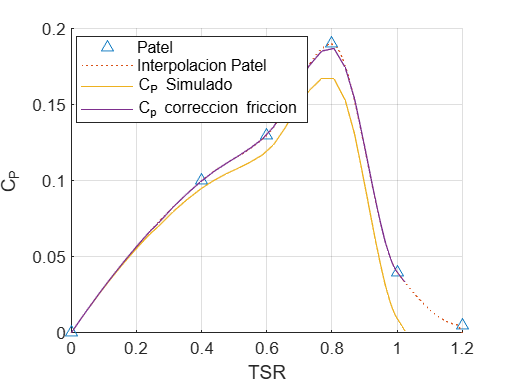


scatter(TSR,Cp_paper,"^")
hold on
plot(xq,Cp(xq),":")
plot(TSR_t,Cp_t)
plot(TSR_t,Cp_t_corregido)
legend("Patel","Interpolacion Patel", "C_P Simulado", "C_p correccion friccion",Location="best")
grid("on")
xlabel("TSR")
ylabel("C_P")
hold off